## Set up

clc
clear
clf
rng(16);

### Preprocessing

FullSet = readtable("process_model\generated_data_take2\training\Noisy\measured_data_combined.csv");
X = FullSet(:,2:3);
X.f_LO_measured = FullSet.f_LO_measured;
X.f_LE_measured = FullSet.f_LE_measured;
X.c_RaffP_measured = FullSet.c_RaffP_measured;
X.c_RaffS_measured = FullSet.c_RaffS_measured;
X.c_BO_measured = FullSet.c_BO_measured;

X_N = normalize(X);

y = FullSet.fault_state;



% Apply LDA for dimensionality reduction on the training data
num_components = 2; % Number of components in the reduced space
lda_model = fitcdiscr(X_N, y); % Fit the LDA model
[eigenvectors, eigenvalues] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, sorted_indices] = sort(diag(eigenvalues), 'descend');
projection_matrix = eigenvectors(:, sorted_indices(1:num_components));

% Project training and testing data onto the LDA components
X_reduced = table2array(X_N) * projection_matrix;

k_values = 1:100;
cv_accuracies = zeros(1,length(k_values));
k_fold = 10;
cv = cvpartition(length(y), 'KFold', k_fold);

for i = 1:length(k_values)
    k = k_values(i);
    accuracies = zeros(1, k_fold);
    
    for fold = 1:k_fold
        trn = training(cv, fold);
        tst = test(cv, fold);
        
        X_train = X_reduced(trn, :);
        y_train = y(trn);
        X_test = X_reduced(tst, :);
        y_test = y(tst);
        
        % Train kNN for current k
        kNN_model = fitcknn(X_train, y_train, 'NumNeighbors', k);
        
        y_pred = predict(kNN_model, X_test);
        
        accuracy = sum(y_pred == y_test) / length(y_test);
        accuracies(fold) = accuracy;
        
    end
    
    cv_accuracies(i) = mean(accuracies);
end
[M, I] = max(cv_accuracies);
best_k = k_values(I);

disp(['Best k: ', num2str(best_k)]);

Best k: 1


disp(['Cross validation accuracy with best k: ', num2str(M)]);

Cross validation accuracy with best k: 0.93334



final_kNN_model = fitcknn(X_train,y_train, 'NumNeighbors', best_k);

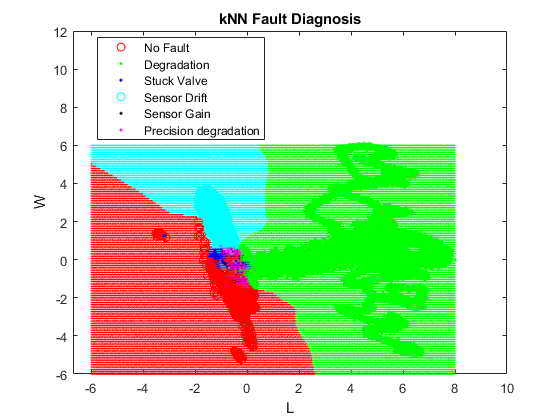

gscatter(X_reduced(:, 1), X_reduced(:, 2), y, 'rgbckm', 'o..');
title('kNN Fault Diagnosis');
xlabel('LDA Component 1');
ylabel('LDA Component 2');

[L, W] = meshgrid(linspace(-6, 8, 500), linspace(-6,6,100)); ...
L = L(:);
W = W(:);
pred = final_kNN_model.predict([L W]);
hold on;
h = gscatter(L, W, pred, 'rgbckm', '.', 1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
legend('No Fault', 'Degradation', 'Stuck Valve', 'Sensor Drift', 'Sensor Gain', 'Precision degradation');
hold off; 
print('process_model/generated_data_take2/training/Noisy/Results/kNN_model', '-dpng', '-r600')


% Predict on the test data and calculate the confusion matrix
y_pred = predict(final_kNN_model, X_test);
C = confusionmat(y_test, y_pred);
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

       34003          22         188          20          11          22
         379        7930          93          15           9          60
        1133         105         616          24          33          57
         228          12          21        5786          17          12
         272           9          24          16          13          13
         469          52          47          20          15          94



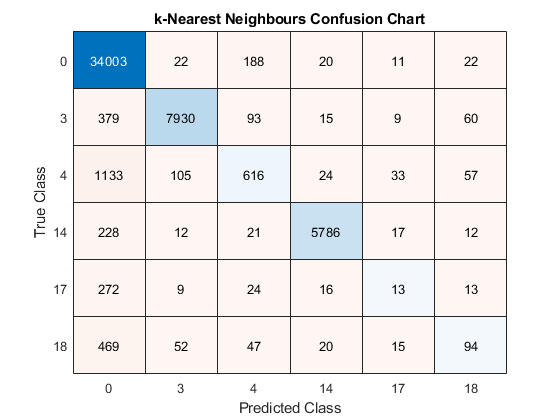


confusionchart(y_test, y_pred)
title('k-Nearest Neighbours Confusion Chart');
print('process_model/generated_data_take2/training/Noisy/Results/kNN_confchart', '-dpng', '-r600')

mean(y_pred == y_test)

ans = 0.9345

Predictions

[ldaPredClass, ldaPredPosterior] = predict(final_kNN_model,X_test);
mean(ldaPredClass == y_test)

ans = 0.9345

50% threshold

sum(ldaPredPosterior(:,1) >= 0.5)

ans = 36484

sum(ldaPredPosterior(:,1) < 0.5)

ans = 15356

ldaPredPosterior(1:20,1).'

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


ldaPredClass(1:20,1).'

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% 90 %
sum(ldaPredPosterior(:,1) >= 0.9)

ans = 36484